clear;clc; %close all;


% figure
vetJ = [0; 0.7; 1];
vetK = [0.32; 0.12; 0];
% scatter(vetJ,vetK,'o')
% title("Coefficient K_T(J)")
% xlabel("J")
% ylabel("K")
% grid on
% hold on
x = vetJ;
y = vetK;
X = [ones(length(x),1) x];
a_matrix = X\y;
y_linfit = X*a_matrix;
% plot(x, y_linfit)
% legend("Experimental data","Linear fit")


#################


run # = 1


m_disp = 3.7792e+04

X_added_mass_disp = -2.9764e+03

X_quad_damp_disp = -8.9941

tempo de assentamento 2% = 481


tempo de alcance = 490.5


erro em regime = -0.0007


força máxima = 654.2534kN


rotação máxima = 0.7146Hz


#################


run # = 2


m_disp = 3.9913e+04

X_added_mass_disp = -4.2328e+03

X_quad_damp_disp = -8.1283

tempo de assentamento 2% = 468


tempo de alcance = 477


erro em regime = 0.0002


força máxima = 708.3854kN


rotação máxima = 0.7436Hz


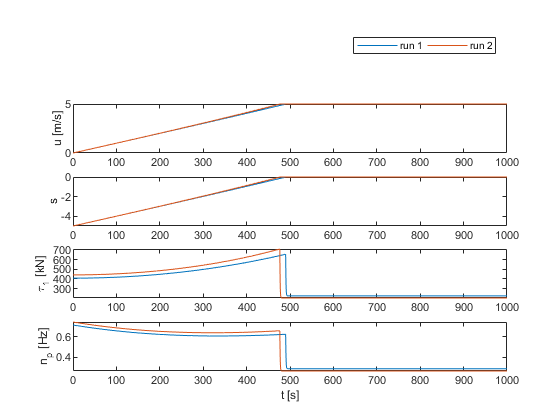

global vetts
vetts = [];
for run = 1:2
    global vetU
    vetU=[];
    global vets
    vets=[];
    global t_simul
    t_simul=[];
    global phi
    phi = 0.01;
    global tr
    tr = 500; % tr = ts para grau=1
    global x0
    x0 = 0;
    global xd
    xd = 5;
    ro = 1.0245;% specific mass of water
    Dp = 7; % thruster diameter
    global std_factor
    disp('#################');
    disp(['run # = ',num2str(run)]);
    %global m X_added_mass X_lin_damp X_quad_damp;
    global m X_added_mass X_quad_damp;
    rng(run) % For reproducibility
    decimal_places = 4;
    std_factor = 0.1;
    m = normrnd(40415,std_factor*40415);
    m_disp = round(m,decimal_places)
    X_added_mass = normrnd(-3375,std_factor*3375);
    X_added_mass_disp = round(X_added_mass,decimal_places)
    X_quad_damp = normrnd(-8.36,std_factor*8.36);
    X_quad_damp_disp = round(X_quad_damp,decimal_places)

    %simulation
    %[t,x] = ode45(@(t,x) sistema(t,x),tspan,x0)
    i = 1;
    dt = 0.5;
    t_end = 1000;
    tspan = 0:dt:t_end;
    vetx = zeros(length(tspan), 1);
    %vetx(1) = x0;
    x = x0;
    for t = tspan
        vetx(i) = x;
        xponto = sistema(t,x);
        x = x+dt*xponto;
        i = i + 1;
    end
    %% metrics
    %tempo de assentamento ts 2%
    idx_x_ts = find(vetx>0.02*(x0-(xd-phi))+(xd-phi), 1);
    ts = tspan(idx_x_ts);
    vetts = [vetts ts];
    disp(['tempo de assentamento 2% = ',num2str(round(ts,decimal_places))]);
    %tempo de alcance ta
    idx_t_ta = find(vets>-phi, 1);
    ta = tspan(idx_t_ta);
    disp(['tempo de alcance = ',num2str(round(ta,decimal_places))]);
    %erro e regime
    e_regime = vetx(end)-xd;
    disp(['erro em regime = ',num2str(round(e_regime,decimal_places))]);
    %tau (cte de tempo)
    %idx_t_slipstart = convert_index(idx_t_simul, t);
    x_slipstart = vetx(idx_t_ta);
    x_tau = x_slipstart + 0.6321*(xd-x_slipstart);
    idx_t_tau = find(vetx>x_tau, 1);
    tau = tspan(idx_t_tau) - tspan(idx_t_ta);
    %disp(['contante de tempo (após s == 0) = ',num2str(tau)]);
    %overshoot = max(vetx) - xd
    
    % aproximacao por uma reta só usando dois pontos de K(J)
    a1 = a_matrix(2); %-0.3;
    b1 = a_matrix(1); % 0.32;
    vetnp = getvetnp(ro,Dp,a1,b1,vetx,vetU);
    disp(['força máxima = ',num2str(round(max(vetU),decimal_places)), 'kN']);
    disp(['rotação máxima = ',num2str(round(max(vetnp),decimal_places)), 'Hz']);
    
    %%plots
    %x
    ax0 = subplot (5,1,1);
    plot(ax0, 1, nan); set(ax0, 'Visible', 'off');
    hold(ax0, 'on')
    
    ax1 = subplot (5,1,2);
    plot(ax1,tspan,vetx)
    ylabel ("u [m/s]")
    %xlabel ("t [s]")
    hold(ax1, 'on')
 
    %s
    ax2 = subplot (5,1,3);
    plot (ax2,tspan,vets)
    ylabel ("s")
    %xlabel ("t [s]")
    hold(ax2, 'on')
    %tau
    ax3 = subplot (5,1,4);
    plot(ax3,tspan,vetU)
    ylabel ("\tau_1 [kN]")
    %xlabel ("t [s]")
    hold(ax3, 'on')
    %np
    ax4 = subplot (5,1,5) ;   
    plot(ax4,tspan,vetnp)
    ylabel ("n_p [Hz]")
    xlabel ("t [s]") 
    hold(ax4, 'on')
    
    lgd = legend(ax0, "run 1","run 2","run 3","run 4","run 5","run 6","run 7","run 8","run 9","run 10");
    %lgd.Orientation = 'horizontal';
    %lgd.Location = 'northoutside';
    lgd.NumColumns = 5;
end

disp("*******************");

*******************


disp(['tempo de assentamento maximo = ',num2str(max(vetts))]);

tempo de assentamento maximo = 481


% np em funcao de tau e dos parametros
syms np_sym Dp_sym u_sym tau_sym ro_sym a_sym b_sym;

% if tau  > 0
np_solutions_sym = simplify(solve(b_sym*(np_sym^2) + ((a_sym*u_sym)/Dp_sym)*np_sym - tau_sym/(ro_sym*Dp_sym^4) == 0, np_sym));

np11 = np_solutions_sym(2);
np11 = simplify(subs(np11, [Dp_sym, ro_sym, a_sym, b_sym], [Dp, ro, a1, b1]))

$$np11 = \frac{310\,u_{\mathrm{sym}}}{4487}+\frac{10\,\sqrt{2049}\,\sqrt{96485361\,{u_{\mathrm{sym}}}^{2}+25319500\,\tau_{\mathrm{sym}}}}{64357041}$$


c1 = double( (10*sqrt(2049)) / ( (64357041 * (1/(sqrt(25319500)))) ) )

c1 = 0.0354

c2 = double(96485361/25319500)

c2 = 3.8107

c3 = double(310/4487)

c3 = 0.0691


np12 = np_solutions_sym(1);
np12 = simplify(subs(np12, [Dp_sym, ro_sym, a_sym, b_sym], [Dp, ro, a1, b1]));

c1 = double( (10*sqrt(2049)) / ( (64357041 * (1/(sqrt(25319500)))) ) );
c2 = double(96485361/25319500);
c3 = double(310/4487);

%%%%%%%%%%%%%%%%%%%%%%%%%%%


%if  tau < 0
np_solutions_sym_2 = simplify(solve(b_sym*(np_sym^2) + ((a_sym*u_sym)/Dp_sym)*np_sym + tau_sym/(ro_sym*Dp_sym^4) == 0, np_sym));

np21 = np_solutions_sym_2(2)

$$np21 = \frac{\sqrt{-\frac{4\,b_{\mathrm{sym}}\,\tau_{\mathrm{sym}}-{{\mathrm{Dp}}_{\mathrm{sym}}}^{2}\,{a_{\mathrm{sym}}}^{2}\,{\mathrm{ro}}_{\mathrm{sym}}\,{u_{\mathrm{sym}}}^{2}}{{\mathrm{ro}}_{\mathrm{sym}}}}-{\mathrm{Dp}}_{\mathrm{sym}}\,a_{\mathrm{sym}}\,u_{\mathrm{sym}}}{2\,{{\mathrm{Dp}}_{\mathrm{sym}}}^{2}\,b_{\mathrm{sym}}}$$

np21 = simplify(subs(np21, [Dp_sym, ro_sym, a_sym, b_sym], [Dp, ro, a1, b1]))

$$np21 = \frac{310\,u_{\mathrm{sym}}}{4487}+\frac{10\,\sqrt{2049}\,\sqrt{96485361\,{u_{\mathrm{sym}}}^{2}-25319500\,\tau_{\mathrm{sym}}}}{64357041}$$


c1 = double( (10*sqrt(2049)) / ( (64357041 * (1/(sqrt(25319500)))) ) )

c1 = 0.0354

c2 = double(96485361/25319500)

c2 = 3.8107

c3 = double(310/4487)

c3 = 0.0691


np22 = np_solutions_sym_2(1);
np22 = simplify(subs(np22, [Dp_sym, ro_sym, a_sym, b_sym], [Dp, ro, a1, b1]));

c1 = double( (10*sqrt(2049)) / ( (64357041 * (1/(sqrt(25319500)))) ) );
c2 = double(96485361/25319500);
c3 = double(310/4487);


%np = c1*sqrt(c2*u_sym^2 + tau_sym) - c3*u_sym
%disp(['n_p = ',char(np), 'Hz']);

% function idx_t = convert_index(idx_t_simul, t)
%     global t_simul;
%     length_t = length(t);
%     length_t_simul = length(t_simul);
%     ratio_t_simul = idx_t_simul/length_t_simul;
%     idx_t = round(length_t*ratio_t_simul);
% end

% vetts = [481, 468, 472.5, 449, 479, 458, 479.5, 463.5, 479.5, 464];
% mean_sample = 469.4;
% sts_sample = 116.93333333333;
% vetts = (vetts-mean_sample)/10.81;
% [h,p] = kstest(vetts,'Alpha',0.025/2)

min(vetU)

ans = 203.2186

function [xponto] = sistema(t,x)
    global X_added_mass; 
    %global X_lin_damp;    
    global X_quad_damp;
    global m;
    global xd;
    global vetU;
    global vets;
    global x0;
    global phi;
    global std_factor;
    global tr;
    
    %f=(X_lin_damp*x+X_quad_damp*x*abs(x))/(m-X_added_mass);
    f = (X_quad_damp*x*abs(x))/(m-X_added_mass);
    ftil = (-8.36*x*abs(x))/(40415-(-3375));
    ftil_params = -8.36/(40415-(-3375));
    % for 95% confidence interval
    Num_mean = -8.36;
    Num_std = abs(std_factor*(-8.36));
    Den_mean = 40415-(-3375);
    Den_std = sqrt((std_factor*40415)^2 + (std_factor*(-3375))^2);
    F = 2*x*abs(x)*abs(ftil_params)*sqrt((Num_std/Num_mean)^2+(Den_std/Den_mean)^2);
   
    % lambda = 1; % lambda nao influencia para grau=1
  
    s = @(xt) (xt-xd);
    vets = [vets s(x)];
    eta = s(x0)/tr;
    k = abs(eta)+F;
    sats = max(-1,min(s(x)/phi,1));
    U = (-ftil-k*sats)*(m-X_added_mass);
    u = U/(m-X_added_mass);
    vetU = [vetU; U];
    xponto = f + u;
end

function vetnp = getvetnp(ro,Dp,a1,b1,vetx,vetU)
   vetnp = double(((sqrt((ro*(Dp^2)*(a1^2)*(vetx.^2)+4*vetU*b1)/(ro)))+Dp*a1*vetx)/(2*(Dp^2)*b1));
end